# Power-Split HEV with Speed Tracking - FTP-75 Drive Cycle

Copyright 2021 The MathWorks, Inc.

## Open the Model

mdl = "PowerSplitHEV_SpeedTracking";
if not(bdIsLoaded(mdl)), open_system(mdl); end

## Load Inputs to Workspace

input_pattern = "ftp75_mph";

FTP-75 drive cycle uses the Drive Cycle Source block from Powertrain Blockset. Plot is not shown in this script.

[inputSignals_DrivingPattern, inputBus_DrivingPattern, initial_DrvPtn, opt1] = ...
  DrivingPatternBasic_inputs( "InputPattern", input_pattern );

drivingPattern.useFromWorkspace_tf = opt1.useFromWorkspace;

Road grade

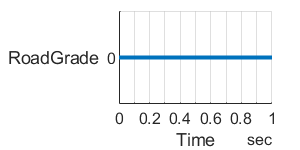

fig = figure;
[inputSignals_RoadGrade, inputBus_RoadGrade, opt2] = ...
  DriverAndEnvironment_road_grade_pattern( "PlotParent",fig, "InputPattern", "flat" );
fig.Position(3:4) = [200 100];  % width height

% Setup simulation time
t_end = max(opt1.t_end, opt2.t_end);

dt = 0;  % 0 for variable-step solver

## Run Simulation

Load default parameters

% Plant
PowerSplitHEV_params

% Controller/Driver - load this after plant
DriverHEVPowerSplit_params

Override initial conditions and block parameter values

% Initial SOC in the controller
%initial.driverHVBattSOC_pct = initial_DrvPtn.HVBattery_SOC_pct;
initial.driverHVBattSOC_pct = 79;

% Initial charge in the plant, which must be consistent with initial SOC
initial.highVoltageBatterySOC_pct = initial.driverHVBattSOC_pct;
initial.hvBatteryCharge_Ah = batteryHighVoltage.nominalCharge_Ah * initial.highVoltageBatterySOC_pct/100;

initial.driverBrakeForce_N = 8000;
initial.driverBrakeOn_tf = true;

initial.vehicleSpeed_kph = 0;
initial.motorGenerator2_speed_rpm = 0;
initial.motorGenerator1_speed_rpm = 0;
initial.engine_speed_rpm = 0;
initial.engine_torque_Nm = 0;

Set simulation input

in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('StopTime',num2str(t_end));

in = in.setModelParameter('SolverName','ode23t');

Run simulation

out = sim(in);

Simulated time (s)

t_end

t_end = 2474

Elapsed wall-clock time (s)

t_elapsed = out.SimulationMetadata.TimingInfo.TotalElapsedWallTime

t_elapsed = 57.8660

Speed up

t_end / t_elapsed

ans = 42.7540

## Visualize Simulation Result

Vehicle

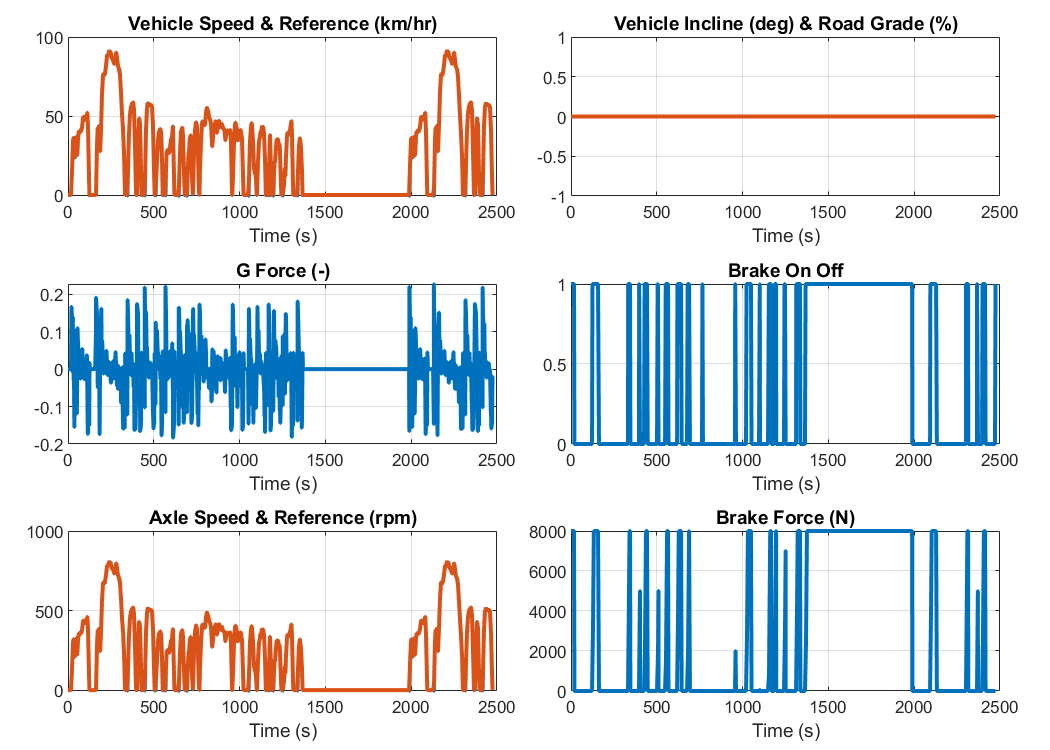

fig = figure;
PowerSplitHEV_SpeedTracking_plot_result_vehicle( "Dataset",out.logsout, "PlotParent",fig );

High Voltage Battery

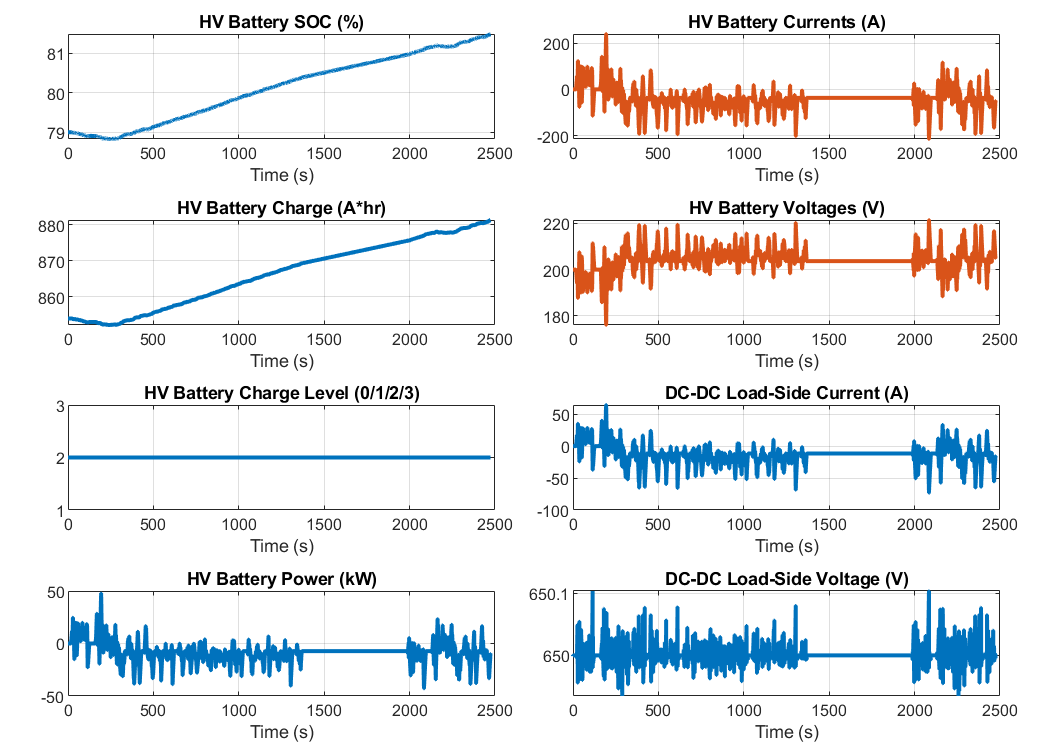

fig = figure;
PowerSplitHEV_SpeedTracking_plot_result_hvbattery( "Dataset",out.logsout, "PlotParent",fig );

Power-Split Drive Unit

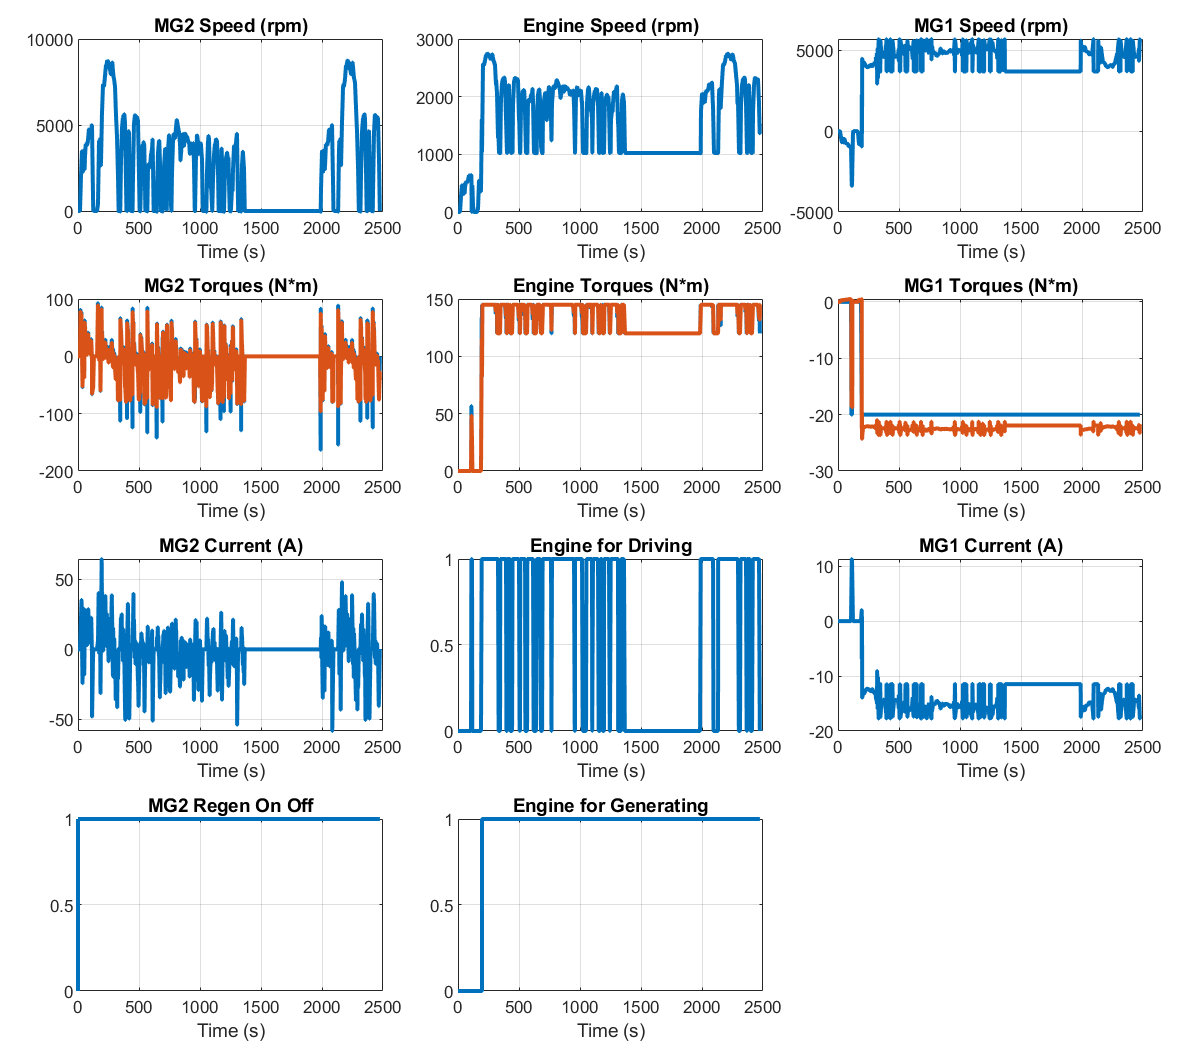

fig = figure;
PowerSplitHEV_SpeedTracking_plot_result_powersplit( "Dataset",out.logsout, "PlotParent",fig );